# Speed and current control tuning

## System parameters

systemParameters

tau_m_eq = 5.6793

## Current loop

### Polo zero cancelation strategy

Simplify transfer function to first order

If $L_a <<<R_a$:


$$F_e \left(s\right)=\frac{k}{\tau {\;}_{e\;} s+1}$$


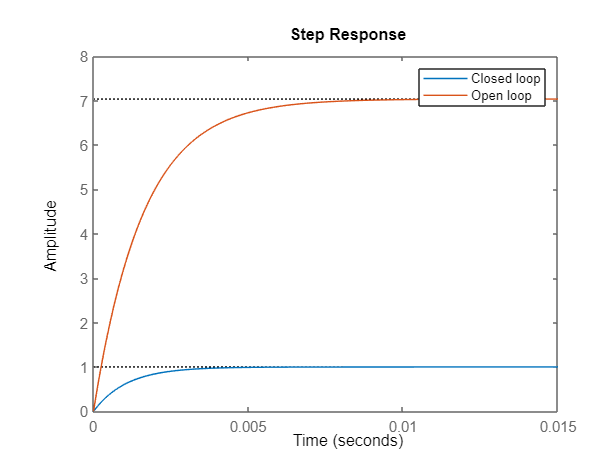

s = tf('s');                % Define Laplace variable
k = (1/Ra);
Fi = k/(tau_e*s+1);     % Transfer function of electrical circuit of DC motor
kx = 1.5;                      % Relation between open and closed loop poles p_la*kx = plc
Ti_i = tau_e;               % Integral time constant [s]
Kp_i = kx*Ti_i/(k*tau_e);     % Proportional gain
Ki_i = 1/Ti_i;               % Integral gain [s]     
Ci = Kp_i*(1+1/(Ti_i*s));   % Currnet PI controller transfer funcion
Fi_cl = feedback(Fi*Ci,1);  % Current control closed loop transfer function
figure
opt = stepDataOptions('InputOffset',0,'StepAmplitude',1);
step(Fi_cl,opt)
hold on
step(Fi,opt)
legend('Closed loop','Open loop')

## Speed loop

### Polo zero cancelation strategy

Simplify transfer function to first order

If $J<<<D$:


$$F_e \left(s\right)=\frac{k}{\tau {\;}_m s+1}$$


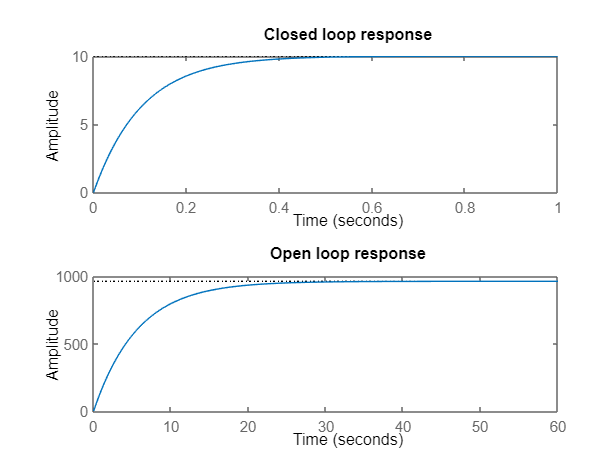

s = tf('s');                % Define Laplace variable
Fw = 1/(J_total*s+D);     % Transfer function of electrical circuit of DC motor
kx = 4;                      % Relation between open and closed loop poles p_la*kx = plc
Ti_w = tau_m_eq;               % Integral time constant [s]
Kp_w = kx*Ti_w/(k*tau_m_eq);     % Proportional gain
Ki_w = 1/Ti_w;               % Integral gain [s]     
Cw = Kp_w*(1+1/(Ti_w*s));   % Currnet PI controller transfer funcion
Fw_cl = feedback(Fw*Cw,1);  % Current control closed loop transfer function
opt = stepDataOptions('InputOffset',0,'StepAmplitude',10);
figure
subplot(211)
step(Fw_cl,opt)
title('Closed loop response')
hold on
subplot(212)
step(Fw,opt)
title('Open loop response')

## Save controller parameters

save controllerParams Kp_i Ki_i Kp_w Ki_w